# Test rendering of derived point cloud and normals

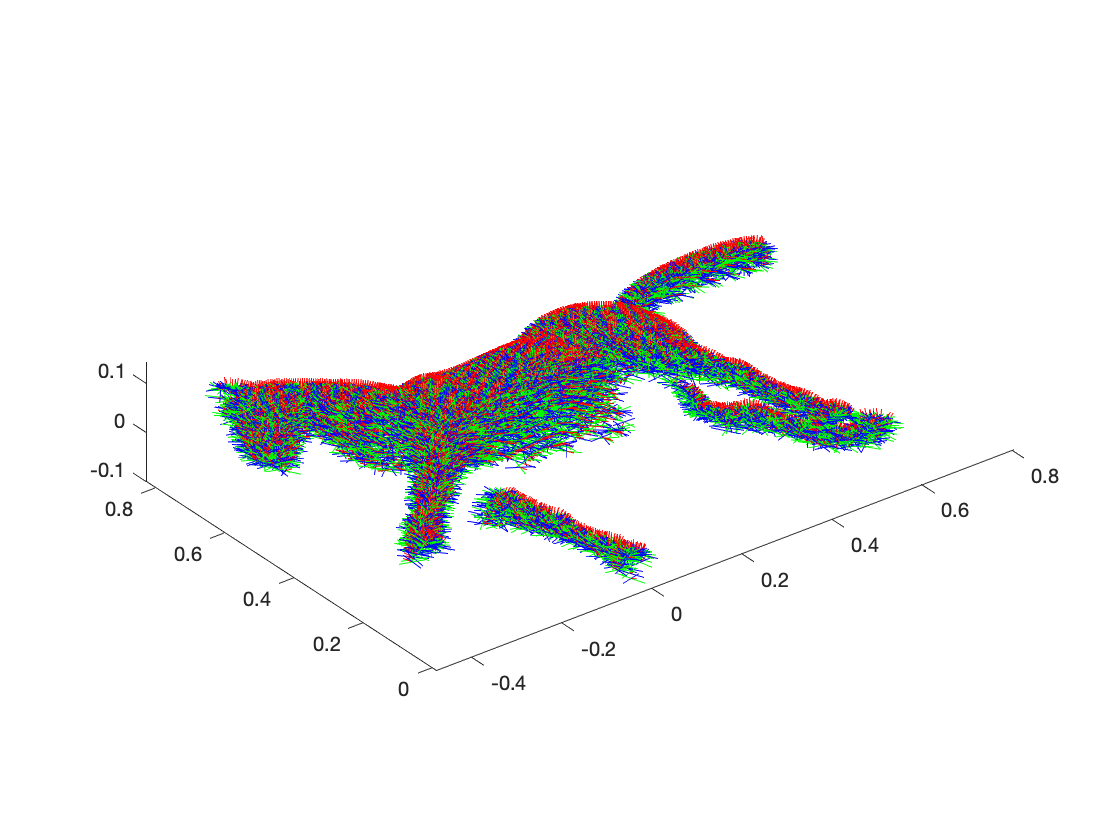

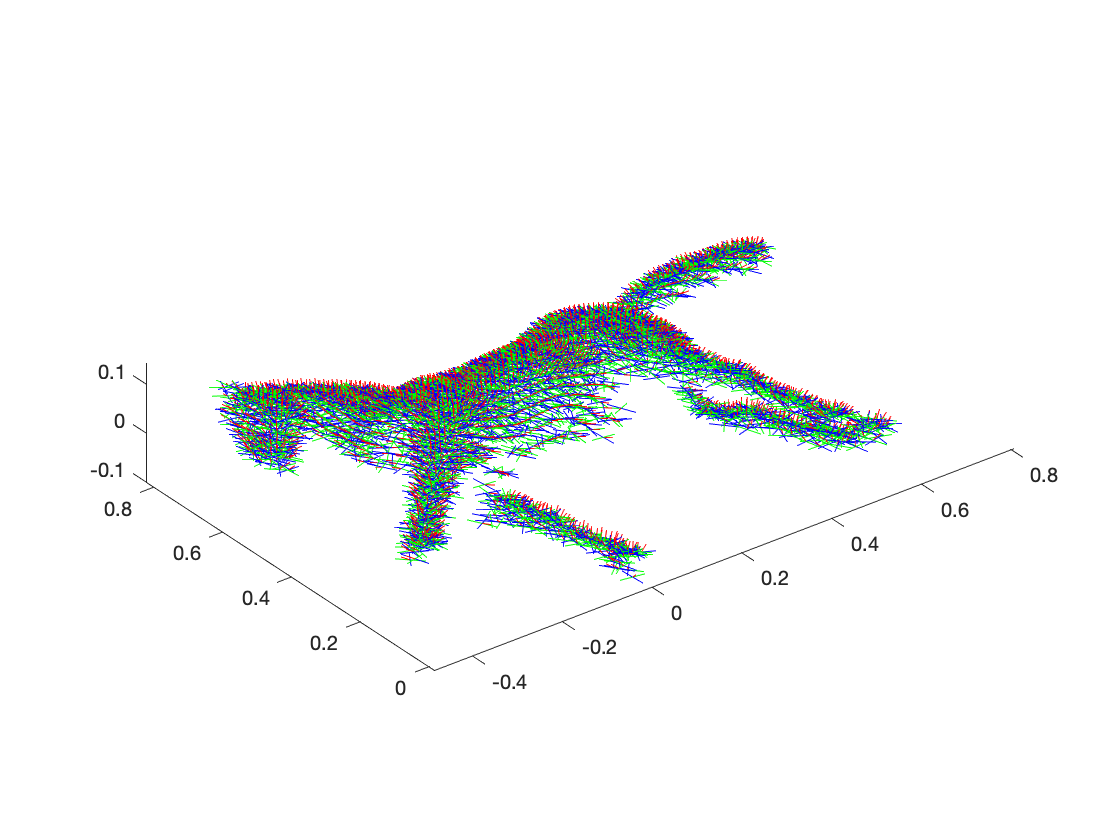

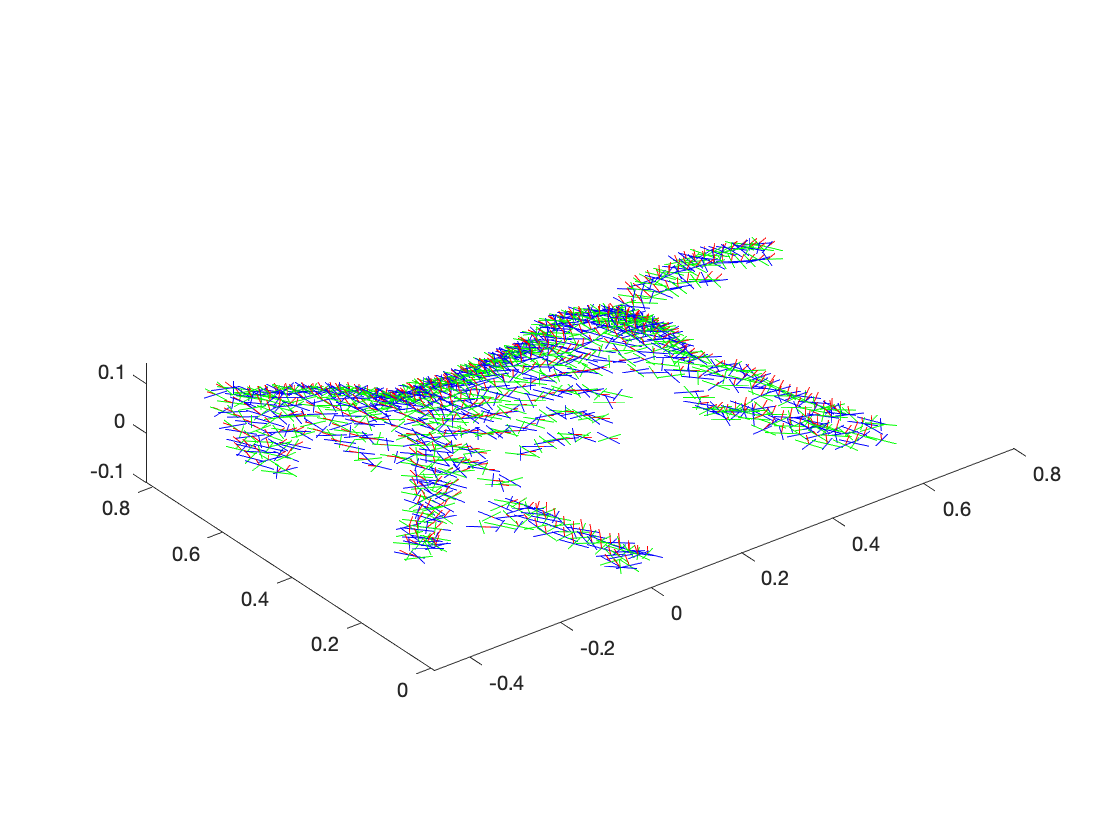

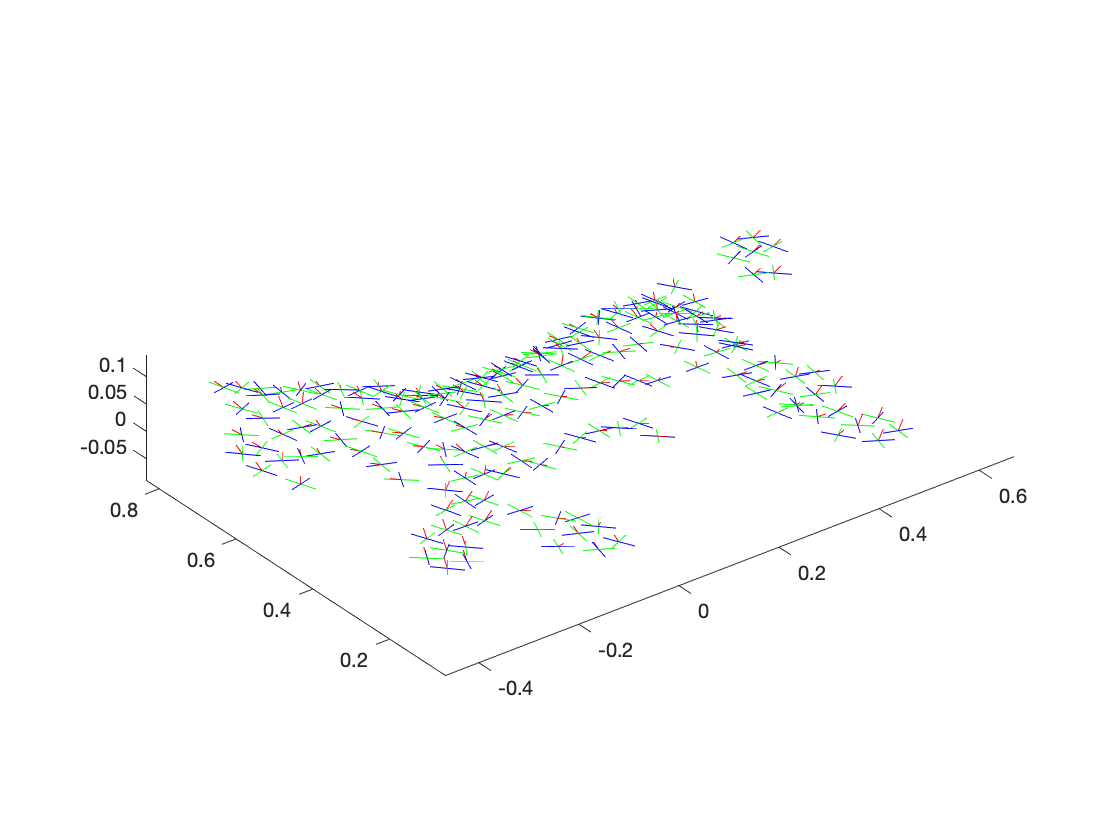

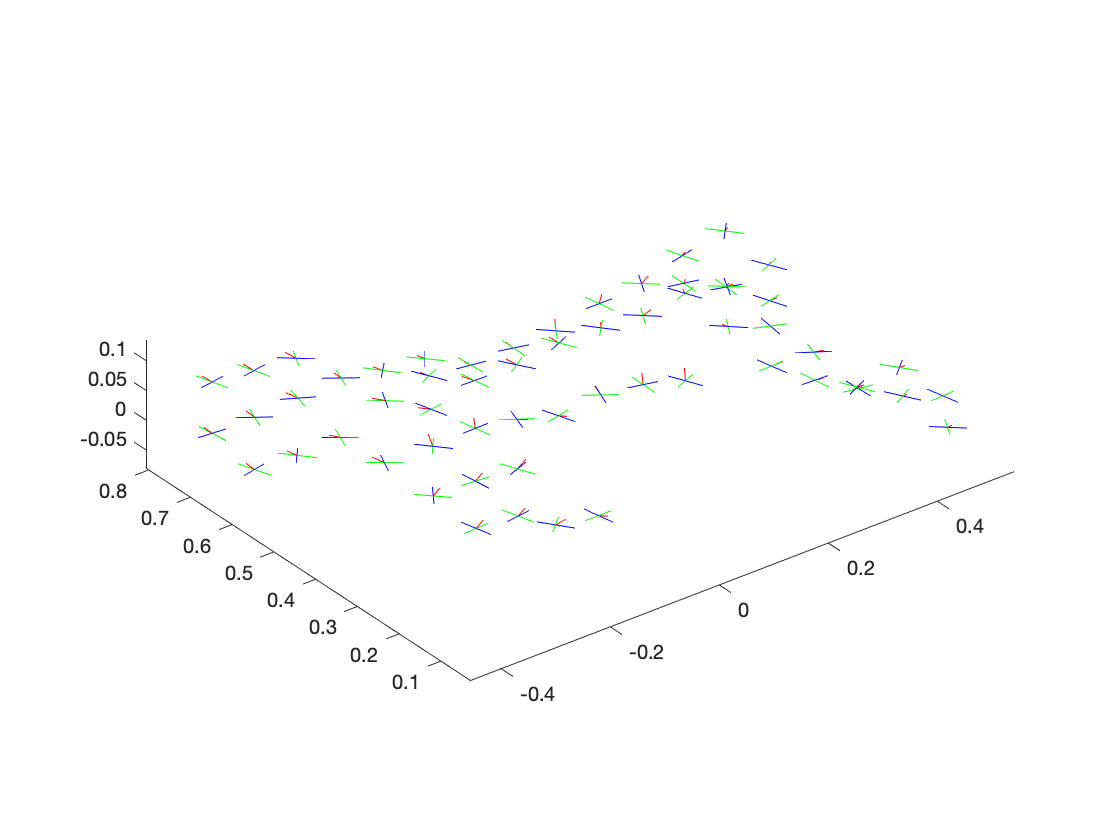

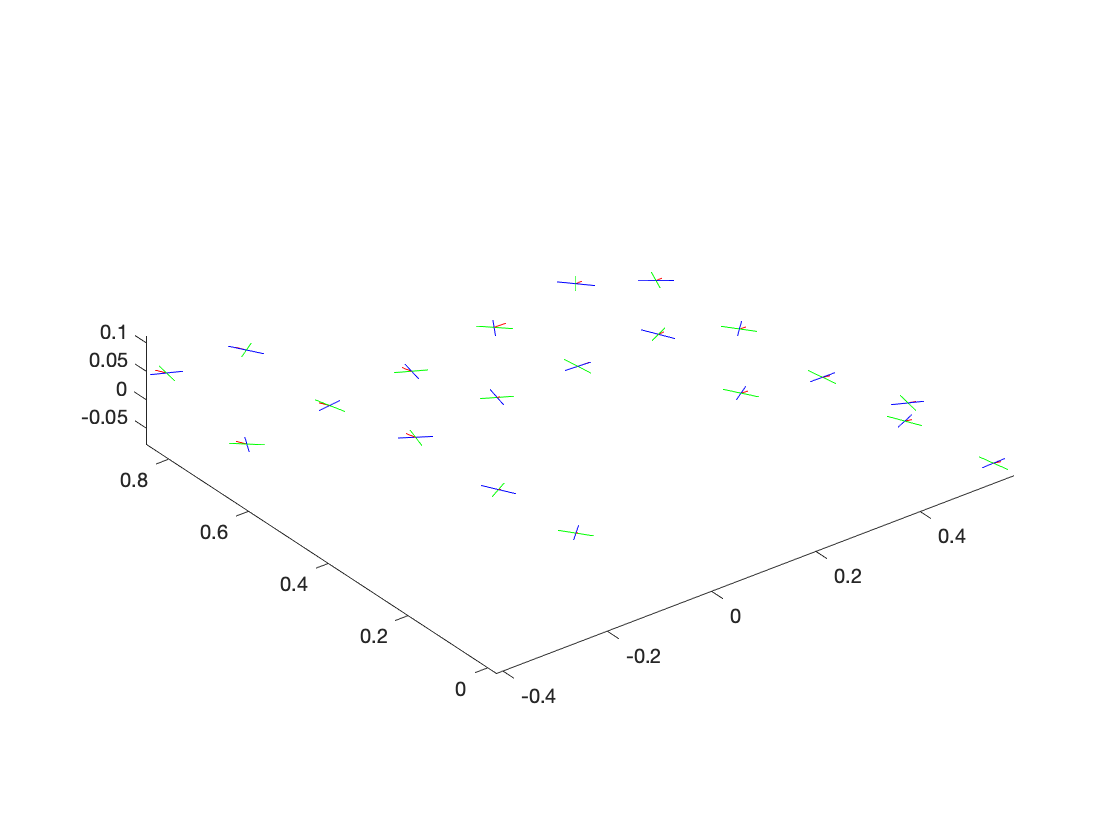

for level=0:5

    point_file_var = sprintf('pointcloudL0%dF00', level);
    norm_file_var = sprintf('normalsL0%dF00', level);
    
    points = table2array(eval(point_file_var));
    norms  = table2array(eval(norm_file_var));
    num_points = size(points,1);

    % Generate surface vectors
    random_unit_vectors = rand(num_points, 3);
    random_unit_vectors = normalize(random_unit_vectors, 2);
    tans = normalize(cross( norms, random_unit_vectors, 2),2);
    tan2 = normalize(cross( norms, tans, 2),2);

    tans = tans * 0.02;
    tan2 = tan2 * 0.02;
    norms = norms * 0.02;

    plot_norms= zeros(num_points * 3, 3);
    plot_norms(1:3:end, :) = points;
    plot_norms(2:3:end, :) = points + norms;
    plot_norms(3:3:end, :) = repmat([nan, nan, nan], size(points,1), 1);

    plot_surf1= zeros(num_points * 3, 3);
    plot_surf1(1:3:end, :) = points - tans;
    plot_surf1(2:3:end, :) = points + tans;
    plot_surf1(3:3:end, :) = repmat([nan, nan, nan], size(points,1), 1);

    plot_surf2= zeros(num_points * 3, 3);
    plot_surf2(1:3:end, :) = points - tan2;
    plot_surf2(2:3:end, :) = points + tan2;
    plot_surf2(3:3:end, :) = repmat([nan, nan, nan], size(points,1), 1);

    figure; %subplot(2,3,level+1)
    plot3( plot_norms(:,1), plot_norms(:,2), plot_norms(:,3), "r" );
    hold on
    plot3( plot_surf1(:,1), plot_surf1(:,2), plot_surf1(:,3), "g" );
    plot3( plot_surf2(:,1), plot_surf2(:,2), plot_surf2(:,3), "b" );
     axis equal

end